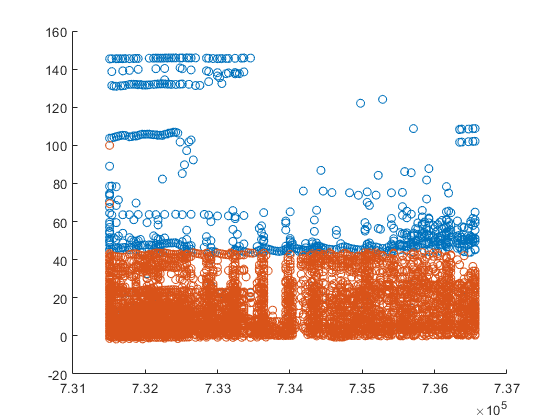

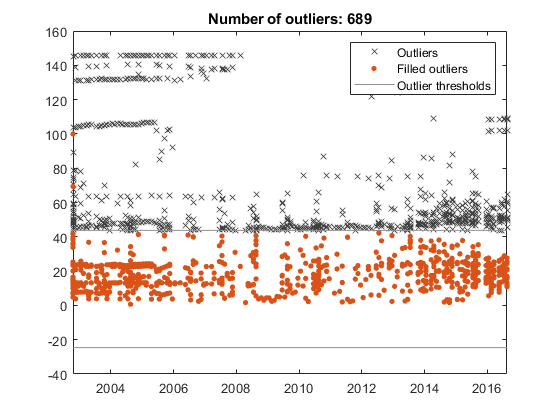

% Fill outliers
[cleanedData,outlierIndices,thresholdLow,thresholdHigh] = filloutliers(GW_f, 'linear', 'ThresholdFactor',3.0);

## Plotting

clf
scatter(TIME_f, GW_f,'DisplayName','Input data')
hold on
%plot(TIME_f, cleanedData,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','Cleaned data')
scatter(TIME_f, cleanedData,'DisplayName','Cleaned data')
hold off

## Plot outliers, fillings and outlier thresh holds


plot(datetime(TIME_f(outlierIndices), 'ConvertFrom','datenum'),GW_f(outlierIndices),'x','Color',[64 64 64]/255,...
    'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices))])

hold on
% Plot filled outliers
plot(datetime(TIME_f(outlierIndices), 'ConvertFrom','datenum'),cleanedData(outlierIndices),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled outliers')

hold on
% Plot outlier thresholds
plot([xlim missing xlim],[thresholdLow*[1 1] NaN thresholdHigh*[1 1]],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

hold off
legend
% clear outlierIndices thresholdLow thresholdHigh

cleanedData2 = cleanedData(1,cleanedData<50)';

